close all;
clc;
clear all;

## Workspace prep

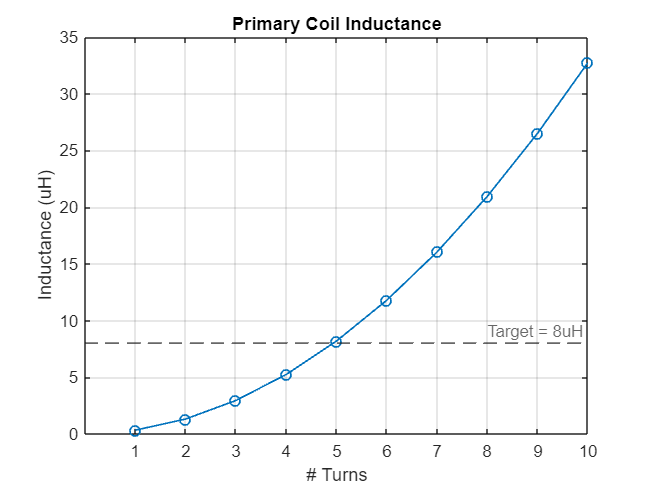

Primary coil ESR: 2.23 mOhm

drsstc_user_constants;          % Load user DRSSTC constants
drsstc_user_params;             % Load user DRSSTC parameters

## GDT DRC

GDT_DRC



################ GDT Params BEGIN ##########################

Volt-time product min: 25.25 V*usec

################ GDT Params END ##########################



## GDT Driver DRC

GDT_DRIVER_DRC

Recommended GDT primary coupling capacitor: 0.1591 uF





################ GDT Driver Params BEGIN ##########################

Peak GDT primary magnitization current: 0.0045 A

RMS GDT primary magnitization current: 0.0026 A(rms)

GDT primary voltage droop percentage w/in tolerance: 0.82 %

################ GDT Driver Params END ##########################



## Topload DRC

TOPLOAD_DRC



################ Topload Params BEGIN ##########################

Estimated topload capacitance: 15.5 pF

################ Topload Params END ##########################



## Secondary Tank DRC

SECONDARY_TANK_DRC



################ Secondary tank Params BEGIN ##########################

Measured topload capacitance: 18.4 pF

Topload capacitance estimate percent error: 19.13 %

################ Secondary tank Params END ##########################



## Bridge DRC

BRIDGE_DRC



################ Inverter Bridge Params BEGIN ##########################

Bridge output impedance approximation: 1.44 Ohm

Bridge minimum snubber capacitance: 0.1163 uF

Bridge peak voltage: 520.00 V

################ Bridge Params END ##########################



## Primary Tank DRC

PRIMARY_TANK_DRC



################ Primary tank Params BEGIN ##########################

Primary coil inductance: 8189.1288 nH

Min primary tank surge impedance: 14.41 Ohm

MMC bank target capacitance: 0.0444 uF

MMC bank capacitance: 0.0450 uF (target: 0.0444 uF, error: 1.40 %)

MMC bank VDC rating: 12.80 kVDC

MMC bank Ipk rating: 540.00 Apk

MMC bank dV/dt rating: 12000 V/usec

MMC bank impedance magnitude: 13.49 Ohm

MMC bank Q factor: 543.95

Actual primary resonant frequency: 262.18 kHz (error: 0.69 %)

Peak voltage seen by MMC bank: 4.05 kV

dV/dt seen by MMC bank: 6667 V/usec

RMS current seen by MMC bank: 31.93 A

Power dissapated by each cap: 1.58 W

Temperature rise above ambient for each cap: 44.24 C

Final temperature for each cap: 66.24 C

MMC bank # of capacitors: 2 parallel branches w/ 8 in series per branch (16 total)

MMC bank total price: 44.48 (USD)

################ Primary tank Params END ##########################



## VBus DRC

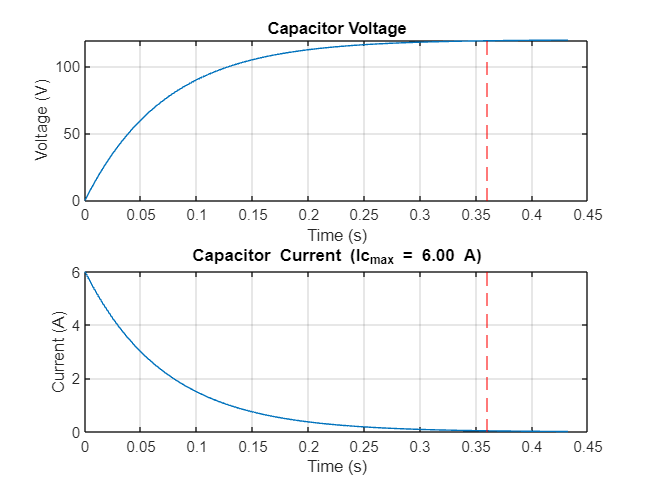

HV Bus bleed resistor: 0.55 kOhm



################ Vbus Params BEGIN ##########################

Bus Voltage: 339.41 V

Balance resistor: 60.40 (actual) 60.3380 (nom.) kOhm

Max voltage across each capacitor: 225.06 V

Voltage droop on bus after 1 PRF cycle (bang): 15.02 %

Bus capacitor bank safe discharge time through balance resistors: 2174.4000 sec

Equivalent bus capacitance: 1800.00 uF

Bulk capacitance configuration: 1 parallel branch(es) w/ 2 cap(s) in series per branch

################ VBus Params END ##########################



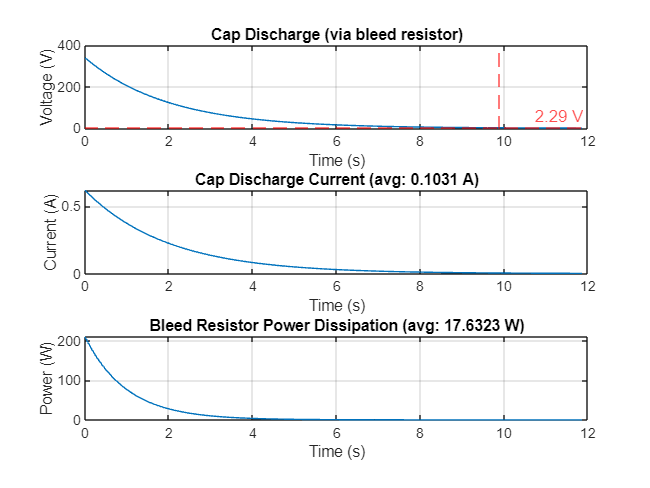

VBUS_DRC

## Current Feedback DRC

CS_DRC



################ Current Sense/Feedback BEGIN ##########################

Max ZCD CT Burden Resistor: 3690987.52 Ohm

################ Current Sense/Feedback END ##########################



## Motherboard DRC

d_max_inch =   894.1560  308.9754  186.7541  133.8193  104.2655   85.4042   72.3214   62.7144   55.3605   49.5502   44.8437   40.9537   37.6847   34.8991   32.4969   30.4041   28.5645   26.9349   25.4811   24.1763


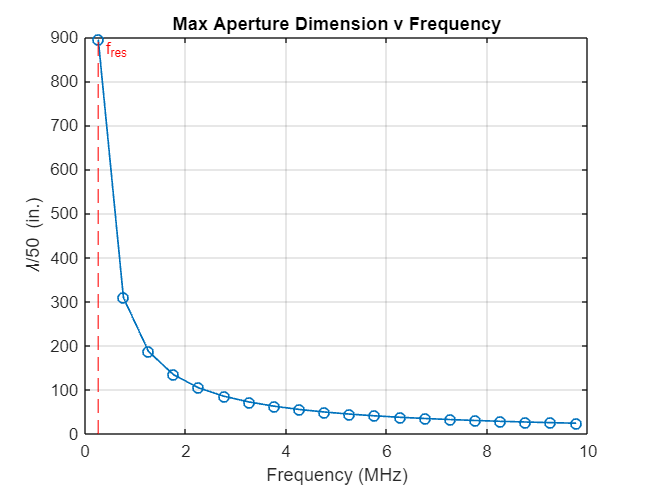

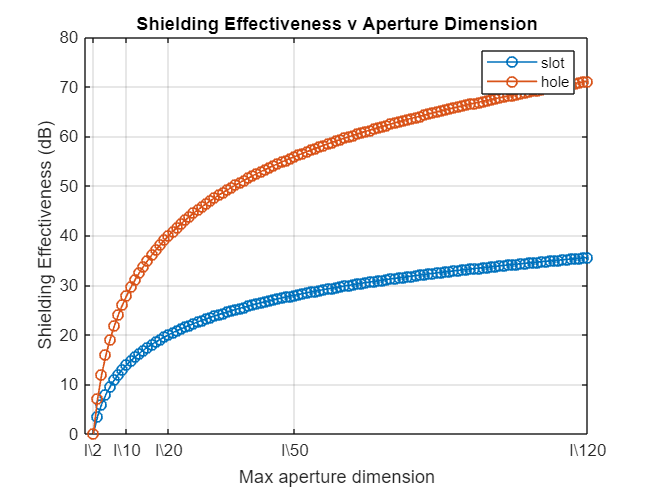

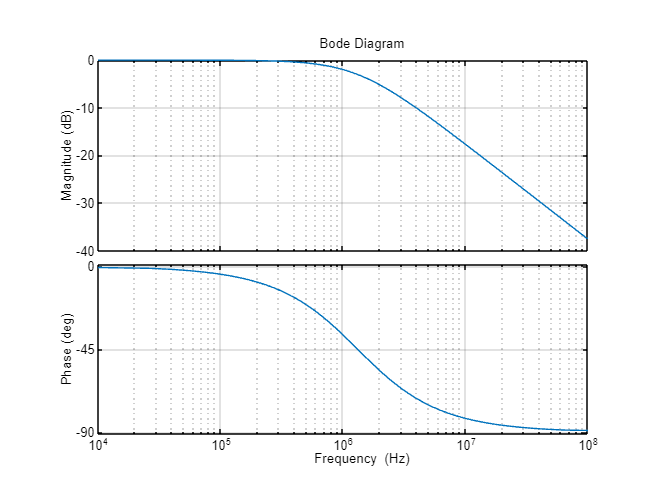



################ ADC Params BEGIN ##########################

ADC sampling frequency: 2.6400 MHz

Anti-aliasing filter R: 100.00 Ohm

Common mode anti-aliasing filter C: 1.2 nF

Common mode anti-aliasing filter cut-off frequency: 1315.33 kHz

Common mode anti-aliasing filter magnitude @ 264.00 kHz: -0.17 dB

Common mode anti-aliasing filter phase @ 264.00 kHz: -11.35 deg

Differential anti-aliasing filter cut-off frequency: 131.75 kHz

Differential anti-aliasing filter C: 6.0 nF

################ ADC Params END ##########################



################ Motherboard Params BEGIN ##########################

Max enclosure opening dimension: 7570.52 mm (298.05 in.)

################ Motherboard Params END ##########################



MB_DRC

## Show Results

Show intermediate and output parameters.

Symbol=["f_{pri}";"f_{sec}"];
Parameter = ["Primary resonant frequency";"Secondary resonant frequency"];
out_params = table(Symbol,Parameter)

out_params = 2×2 table
     Symbol                Parameter           
    _________    ______________________________

    "f_{pri}"    "Primary resonant frequency"  
    "f_{sec}"    "Secondary resonant frequency"
